Ny = 250;
Nx = 3*Ny;

h = (Ny*0.2);
d = (Nx*0.2);
W1= zeros(Nx,Ny,4);

for i = 1:d
    for j = 3:Ny
        W1(i,j,:) = W(i,j,:);
    end
end

for i = d+1:Nx
    for j = h+1:Ny
        W1(i,j,:) = W(i,j,:);
    end
end


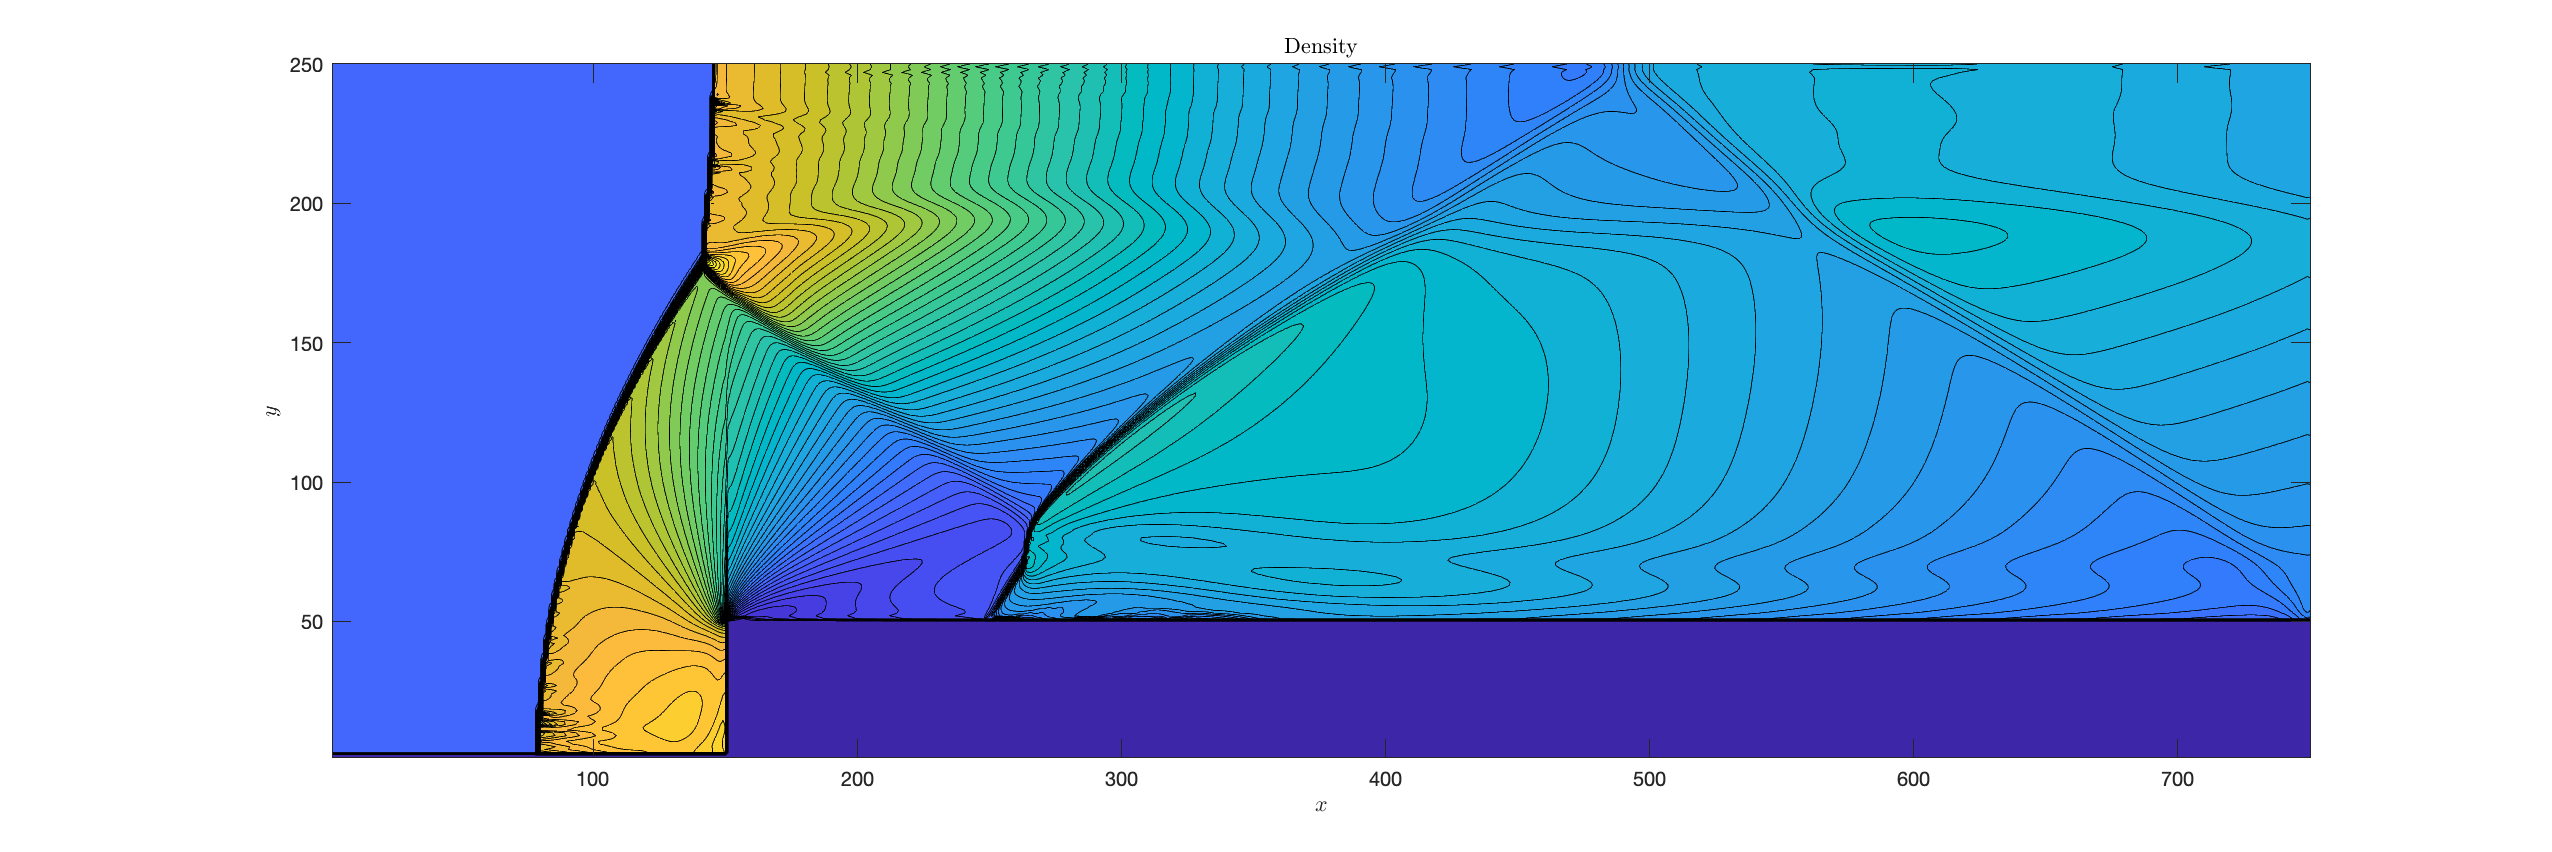

contourf(W1(:,:,1),60);
% s = pcolor(W1(:,:,4));
% s.LineWidth = 0.01;
% mat = reshape(W1(:,:,1),Nx,Ny);
% mat = mat';
% heatmap(mat)

set(gcf,'unit','centimeters','position',[10 10 45 15]);
view(90,-90)
xlabel('$y$','interpreter','latex');
ylabel('$x$','interpreter','latex');

title(sprintf('Density'),'interpreter','latex')

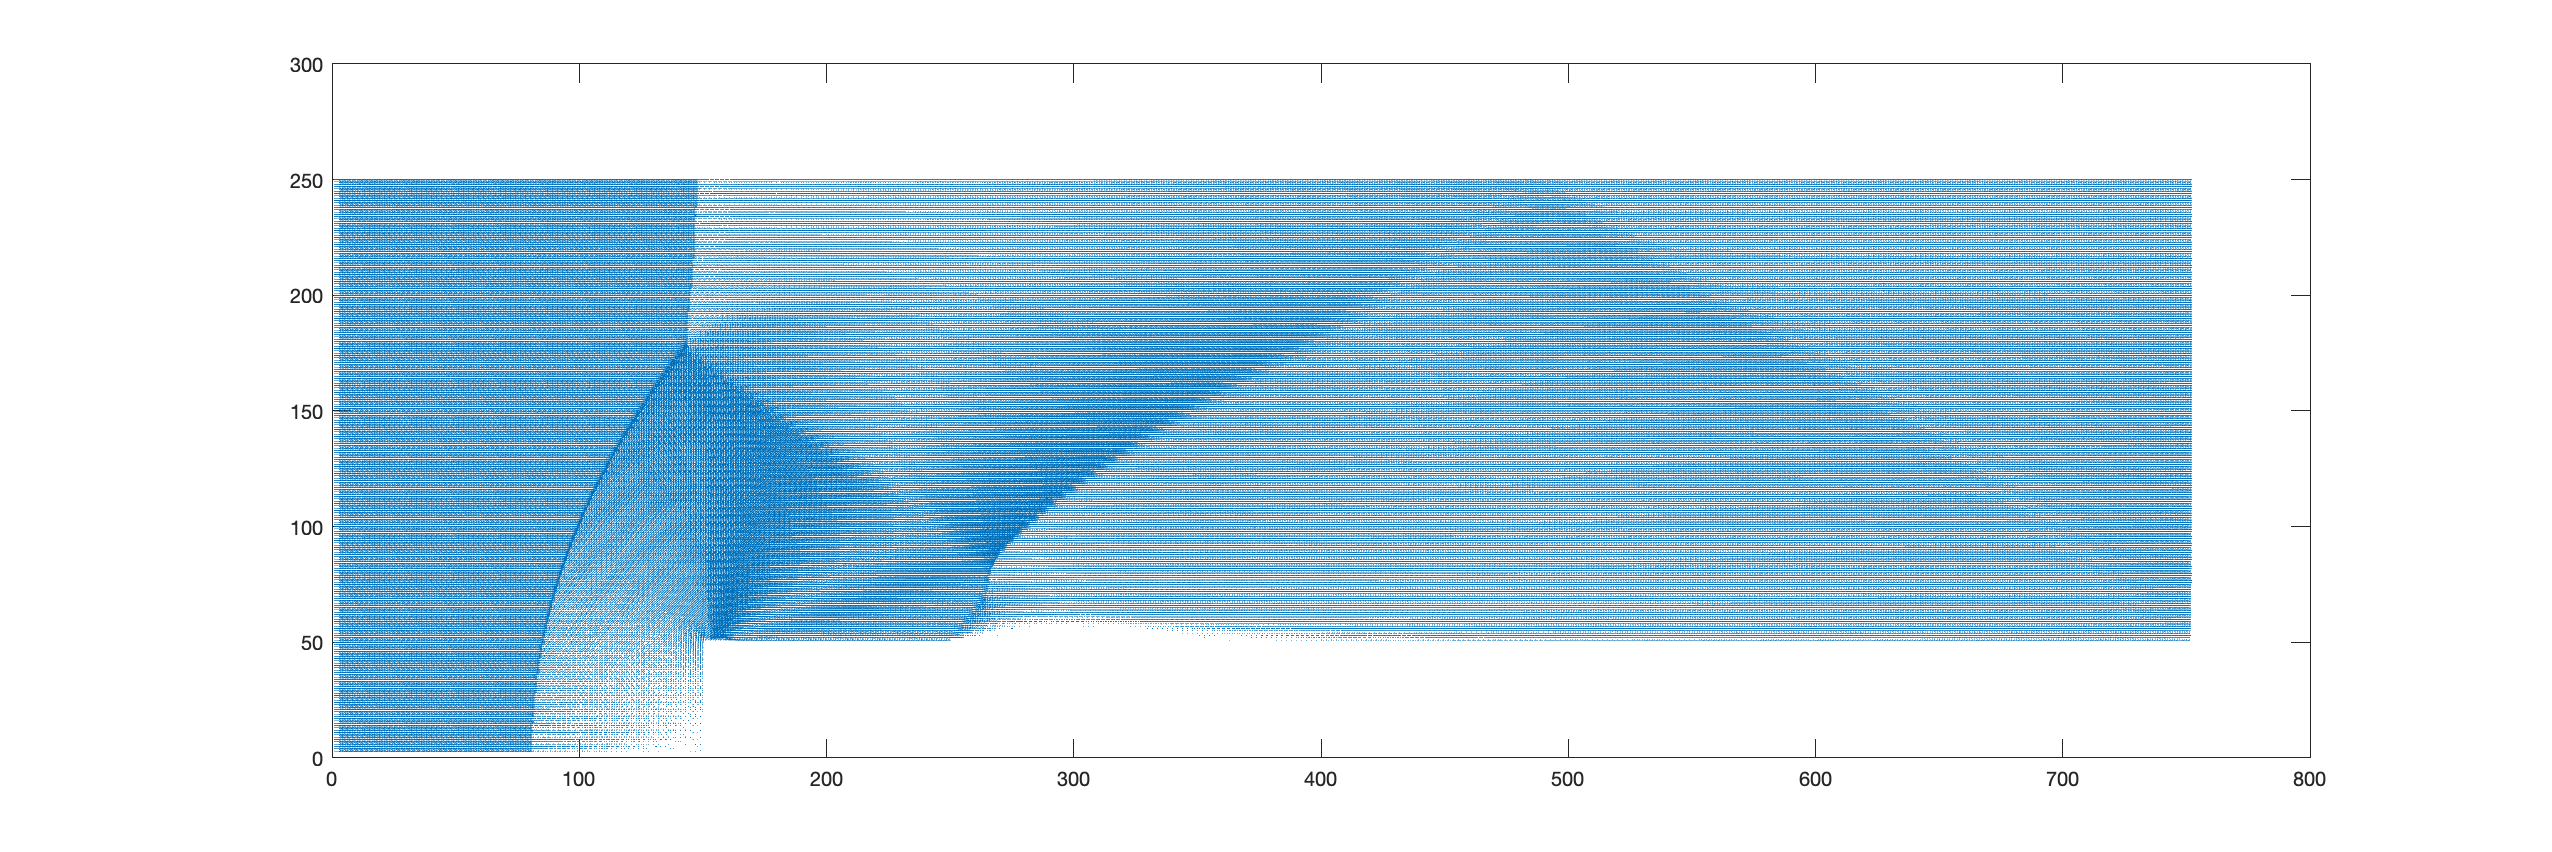

quiver(W1(:,:,3),W1(:,:,2),0)
view(90,-90)

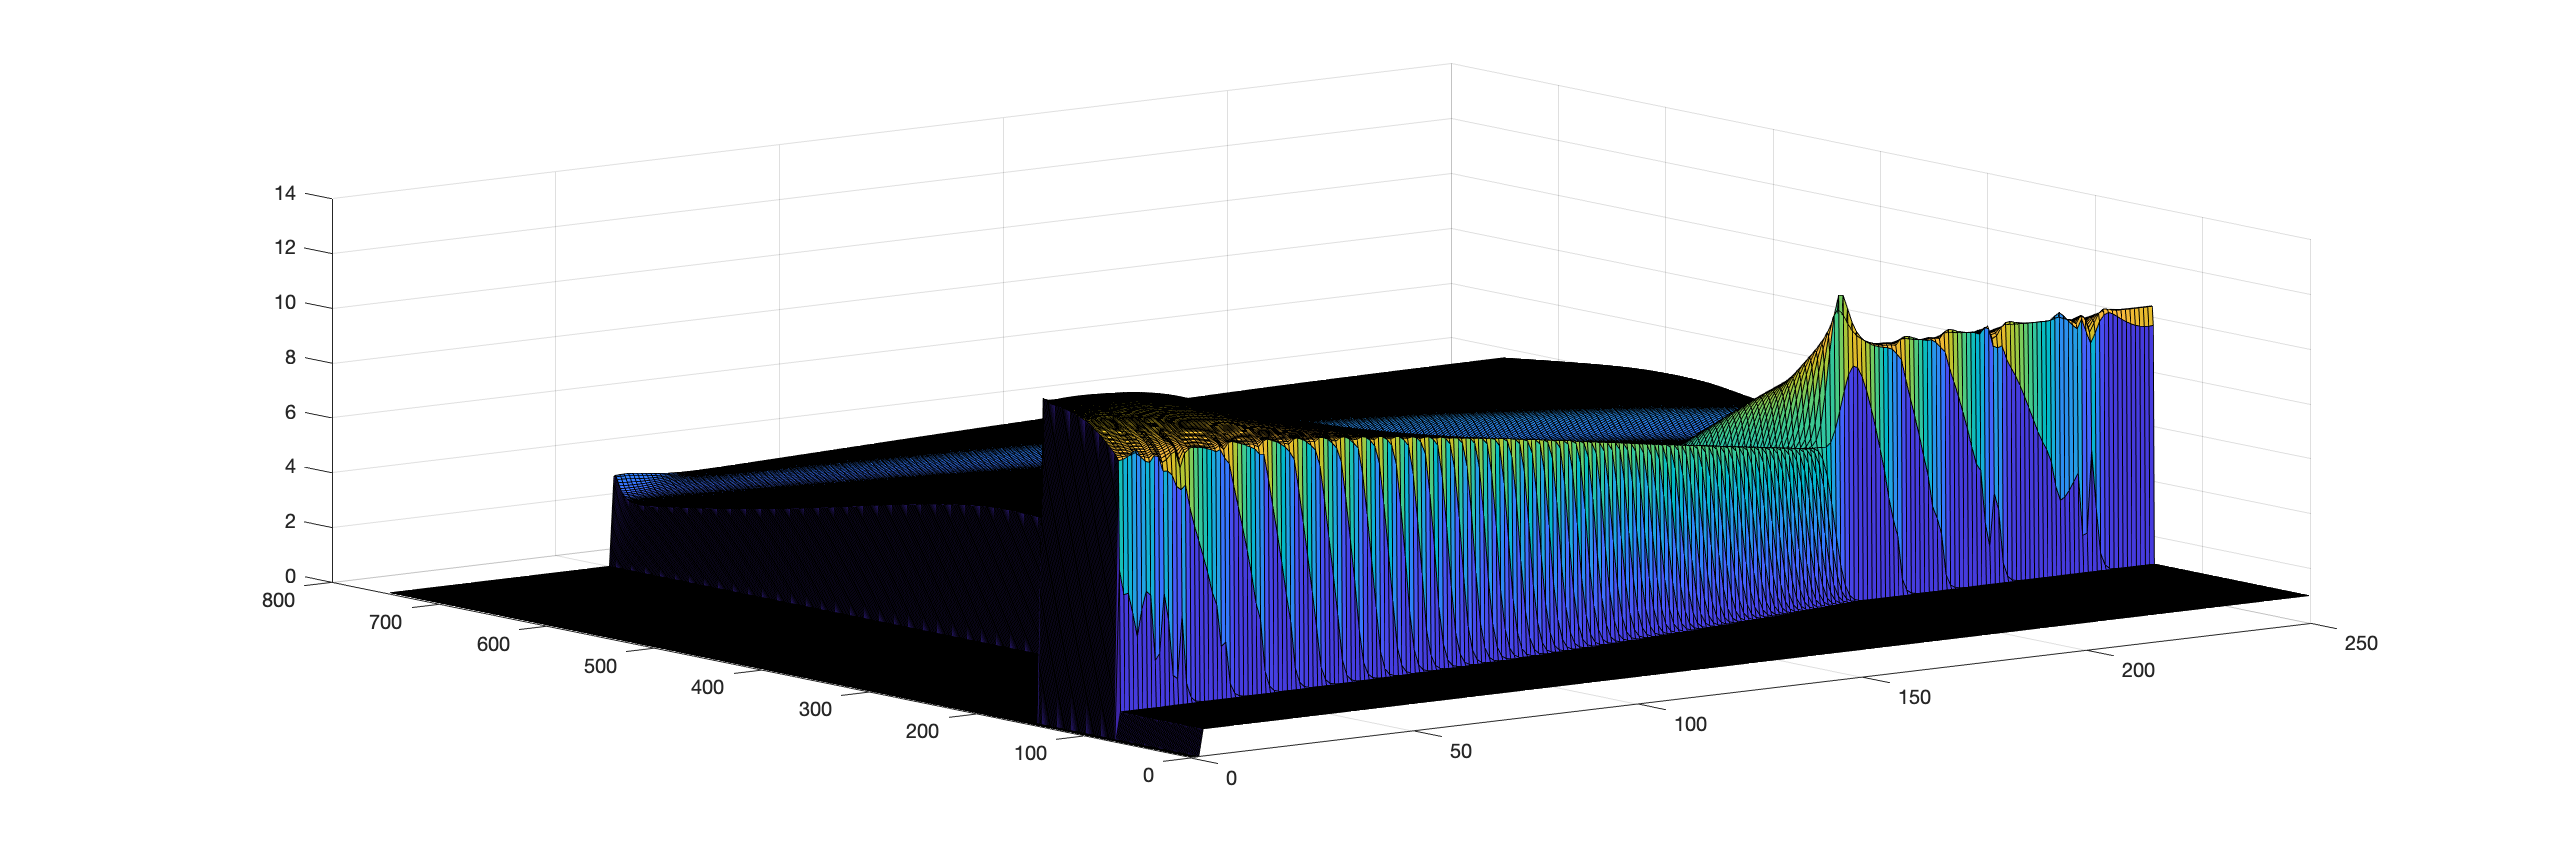

surf(W1(:,:,4))

% view(90,-90)


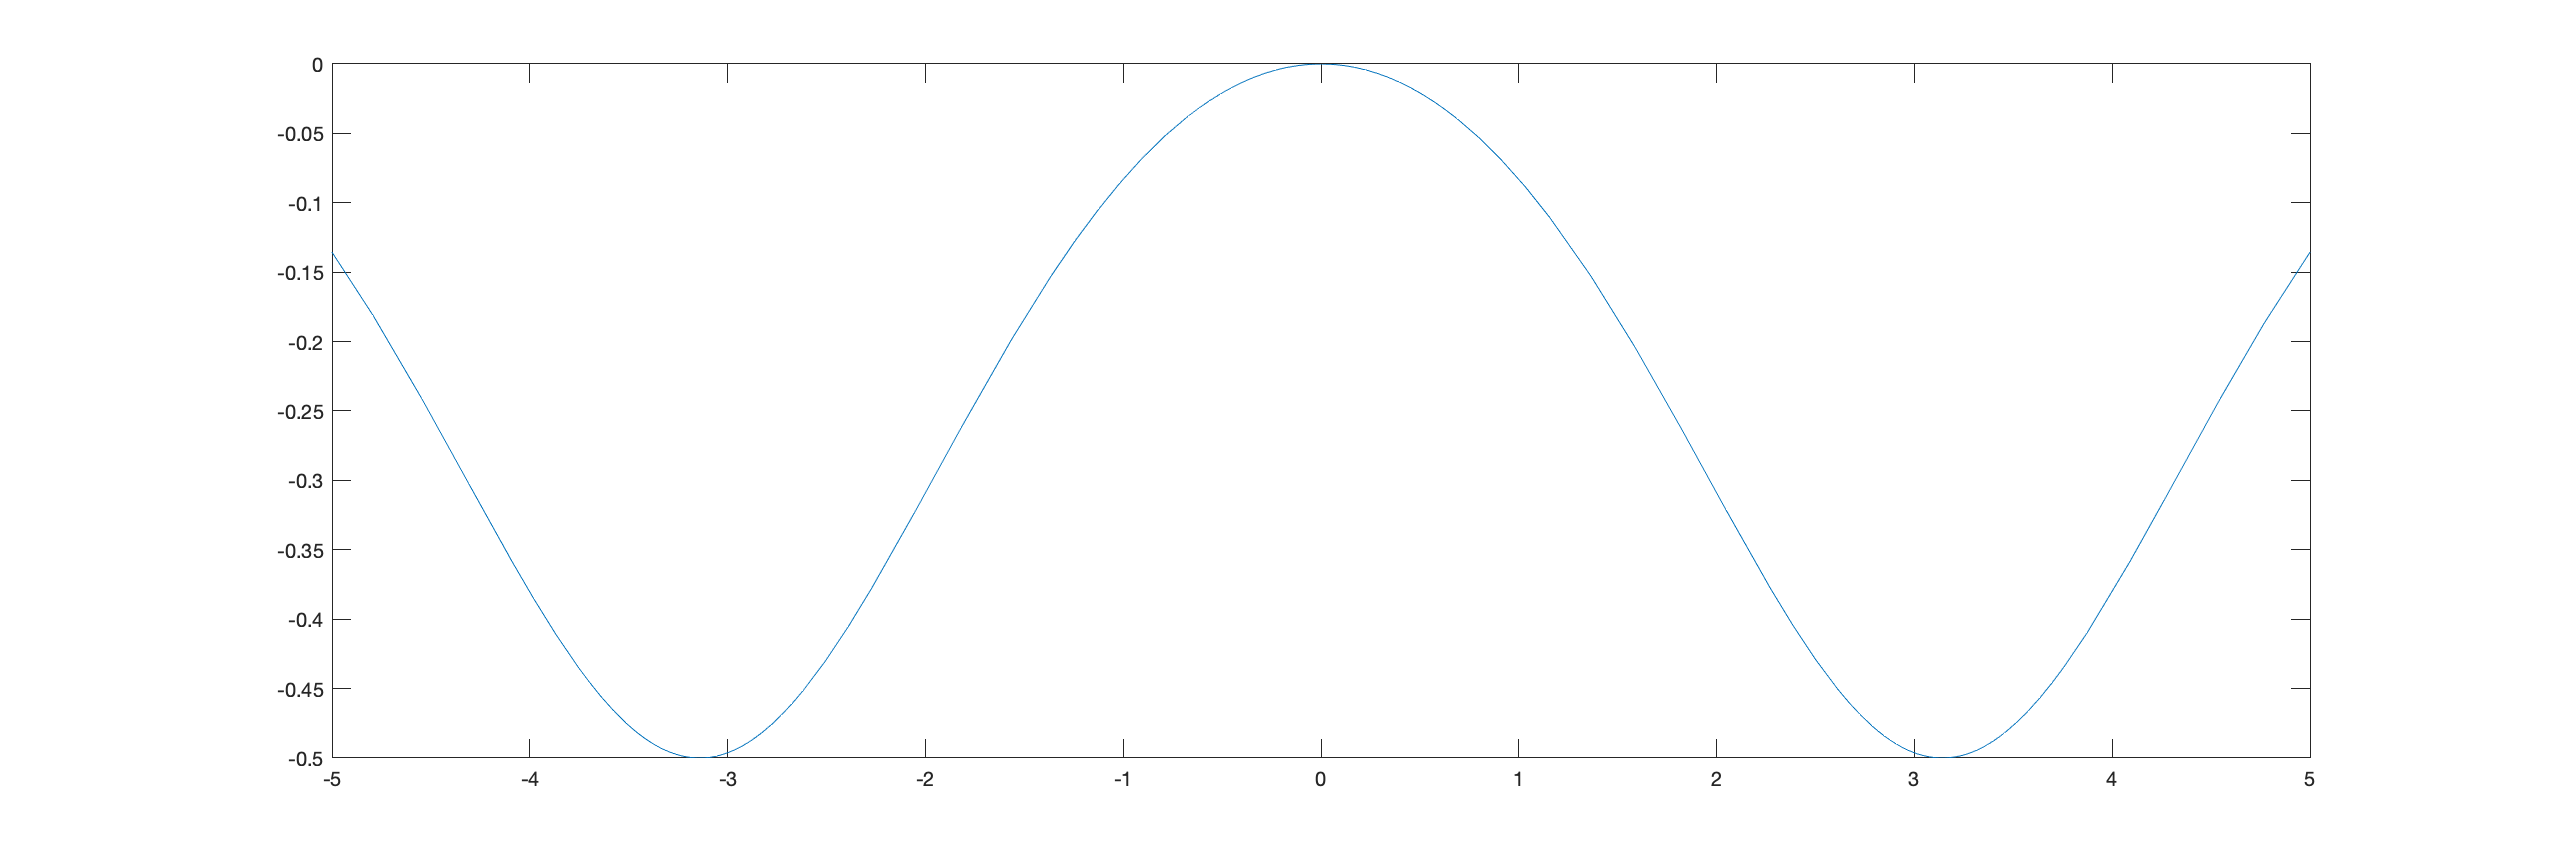

syms x
fplot((cos(x)-1)/(cos(x)+5))

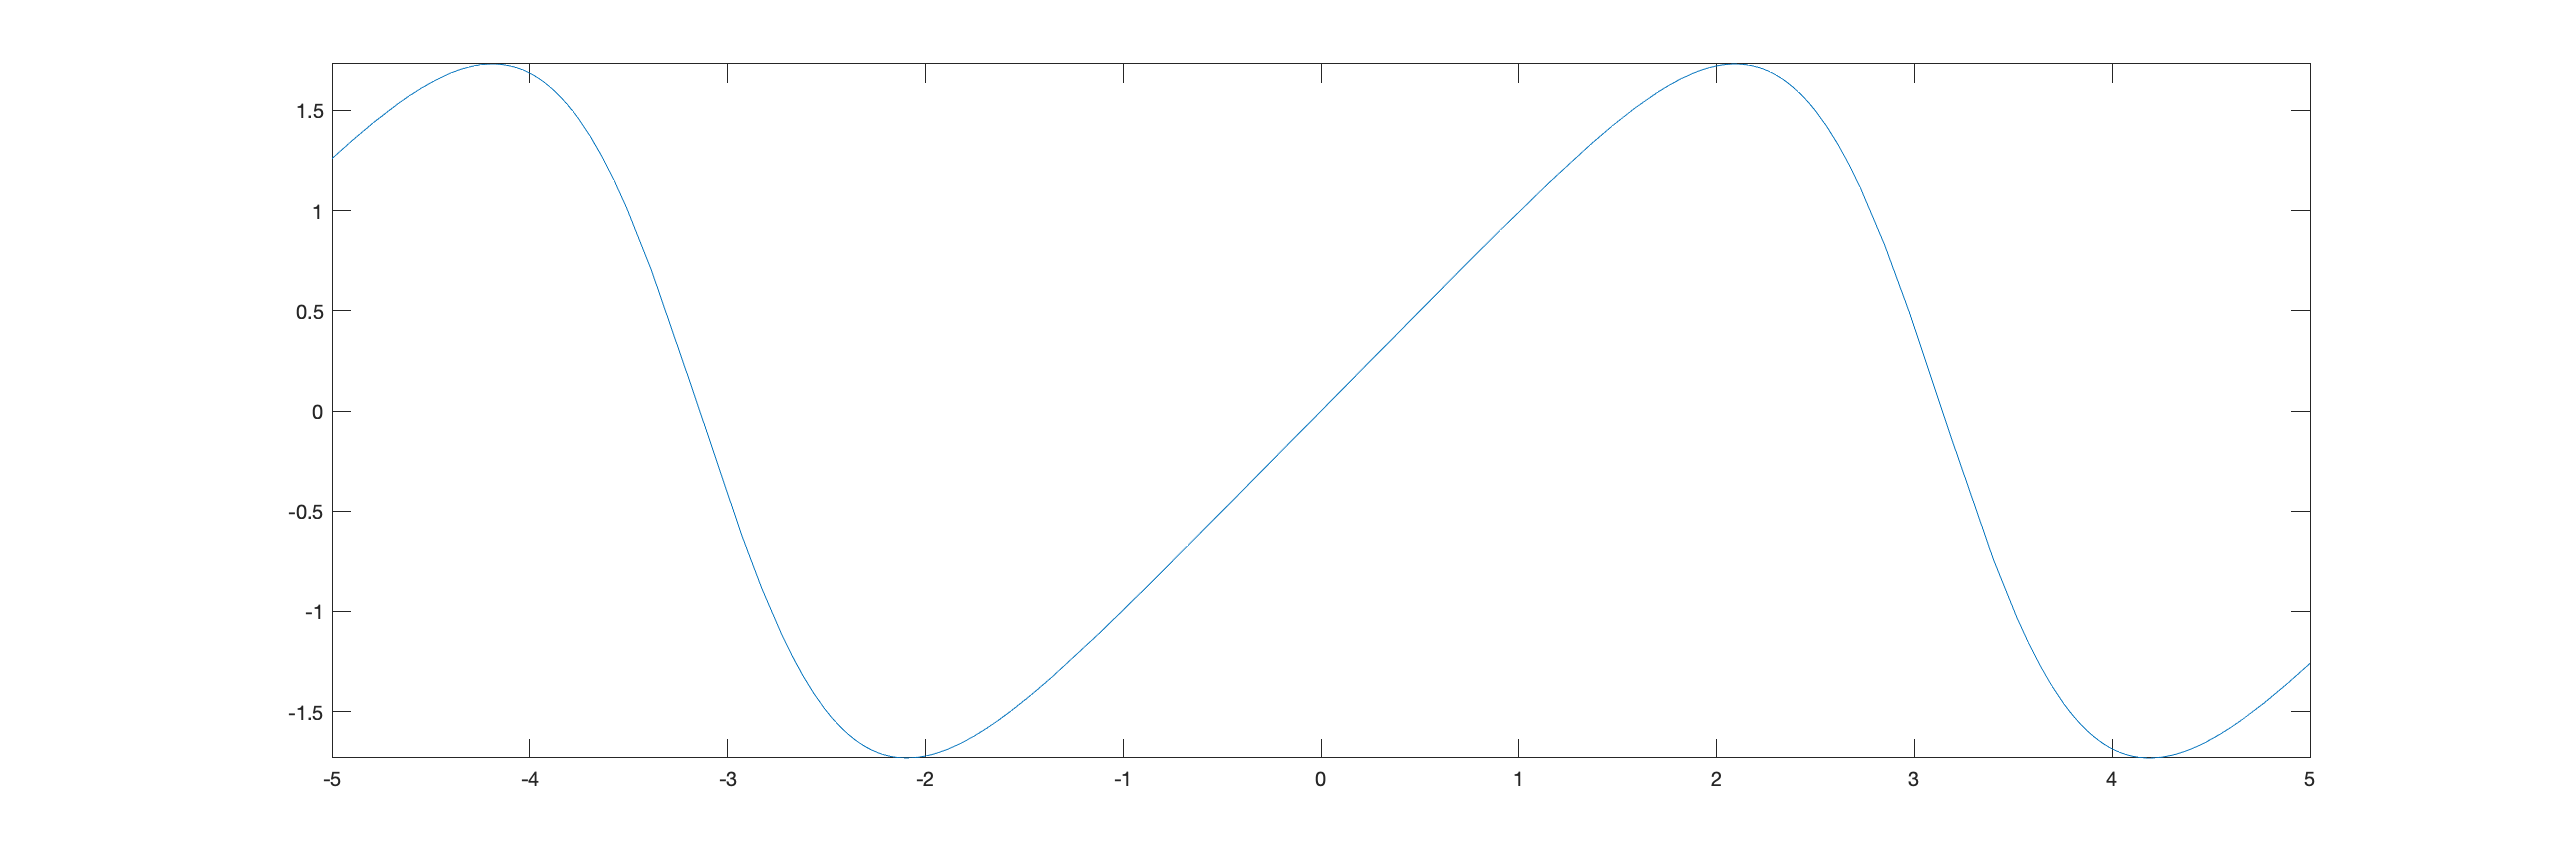


fplot(3*sin(x)/(2+cos(x)))